% Beach Rescue Drone Acoustic Simulation (30s Ocean + Drone + Repeating Seagulls)
clear; clc;

% --- 1. SETTINGS ---
fs = 44100;           % Audio sampling rate (Hz)
dur = 30.0;           % Duration extended to 30 seconds
t = 0:1/fs:dur-1/fs;  % Time vector

fprintf('Synthesising 30 seconds of Surf, Drone, and Seagulls...\n');

Synthesising 30 seconds of Surf, Drone, and Seagulls...



% --- 2. OCEAN NOISE (Violent Crashing Surf) ---
ocean_raw = randn(1, length(t));
[b_ocean, a_ocean] = butter(4, 3500/(fs/2), 'low'); 
ocean_noise = filter(b_ocean, a_ocean, ocean_raw);

wave_lfo = (sin(2 * pi * 0.25 * t - pi/2) + 1) / 2; 
wave_lfo = wave_lfo.^3; 
wave_lfo = wave_lfo * 0.85 + 0.15; 

ocean_noise = ocean_noise .* wave_lfo;
ocean_noise = ocean_noise / max(abs(ocean_noise));


% --- 3. RESCUE DRONE NOISE (150 Hz Fundamental) ---
fund_freq = 150; 
drone_motor = zeros(1, length(t));

for h = 1:15
    drone_motor = drone_motor + (1/h) * sin(2 * pi * (fund_freq * h) * t);
end

prop_wash = randn(1, length(t));
[b_wash, a_wash] = butter(4, [800 2500]/(fs/2), 'bandpass');
prop_wash = filter(b_wash, a_wash, prop_wash);

drone_noise = drone_motor + (0.8 * prop_wash);
drone_noise = drone_noise / max(abs(drone_noise));


% --- 4. SEAGULL NOISE SYNTHESIS (Repeating Clusters) ---
seagull_noise = zeros(1, length(t));

% Generate repeating clusters of calls across the 30 seconds
call_times = [];
for sec = 1.5 : 6 : (dur - 3) % Every 6 seconds, spawn a new cluster of birds
    cluster = [sec, sec + 0.6, sec + 2.3]; % 3 squawks per cluster
    call_times = [call_times, cluster];
end

for c = 1:length(call_times)
    start_idx = round(call_times(c) * fs);
    call_dur = 0.35; % 350ms squawk duration
    call_samples = round(call_dur * fs);
    
    if start_idx + call_samples - 1 <= length(t)
        t_call = linspace(0, call_dur, call_samples);
        
        % FM Synthesis: Pitch sweeps downward from 1600 Hz to 1100 Hz
        phase = 1600*t_call - (714)*t_call.^2;
        
        % Fundamental + 2nd Harmonic + 3rd Harmonic
        caw = sin(2 * pi * phase) + 0.6 * sin(2 * pi * 2 * phase) + 0.3 * sin(2 * pi * 3 * phase);
        
        % Attack/Decay Envelope
        env_caw = sin(pi * t_call / call_dur) .* exp(-4 * t_call);
        
        seagull_noise(start_idx:start_idx+call_samples-1) = caw .* env_caw;
    end
end
seagull_noise = seagull_noise / max(abs(seagull_noise));


% --- 5. MIXING THE ENVIRONMENT ---
ocean_vol = 0.65;  % 65% Surf
drone_vol = 0.20;  % 20% Drone hum
gull_vol  = 0.15;  % 15% Piercing seagulls

% Mix them together
ambient_environment = (ocean_noise * ocean_vol) + (drone_noise * drone_vol) + (seagull_noise * gull_vol);
ambient_environment = ambient_environment / max(abs(ambient_environment));


% --- 6. AUDIO PLAYBACK & EXPORT ---
disp('Playing 30-second simulation over speakers...');

Playing 30-second simulation over speakers...


fade = round(fs * 0.1); 
env = ones(1, length(ambient_environment));
env(1:fade) = linspace(0, 1, fade);
env(end-fade+1:end) = linspace(1, 0, fade);
final_audio = ambient_environment .* env * 0.8;

% Play the sound
sound(final_audio, fs);

% Save to a WAV file so you can put it on your phone
filename = 'Rescue_Drone_Beach_Sim_30s.wav';
audiowrite(filename, final_audio, fs);
fprintf('Success! Saved audio file as: %s\n', filename);

Success! Saved audio file as: Rescue_Drone_Beach_Sim_30s.wav


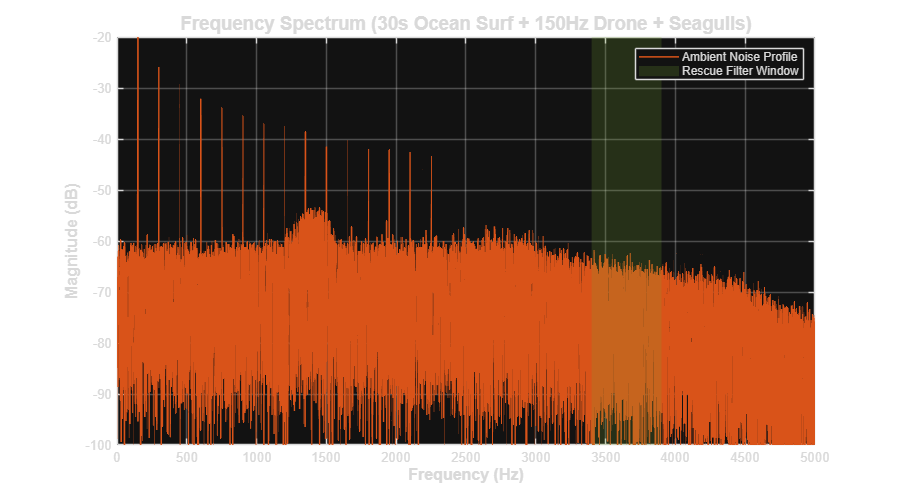



% --- 7. FREQUENCY SPECTRUM PLOT (FFT) ---
N = length(ambient_environment);
Y = fft(ambient_environment);
P2 = abs(Y/N);            
P1 = P2(1:N/2+1);         
P1(2:end-1) = 2*P1(2:end-1);
f = fs*(0:(N/2))/N;       

figure('Name', 'Rescue Drone Frequency Analysis', 'Color', 'w', 'Position', [100, 100, 900, 500]);
plot(f, 20*log10(P1), 'Color', '#D95319', 'LineWidth', 1.2);
hold on; grid on;

patch([3400 3900 3900 3400], [-120 -120 0 0], [0.4660 0.6740 0.1880], ...
    'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', 'Target Filter Zone (3.4 - 3.9 kHz)');

title('Frequency Spectrum (30s Ocean Surf + 150Hz Drone + Seagulls)', 'FontSize', 14);
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');

xlim([0 5000]); 
ylim([-100 -20]);

% Labels (Uncommented and adjusted for visibility)
%text(150, -25, '\leftarrow Drone', 'FontSize', 10, 'FontWeight', 'bold');
%text(1600, -35, '\leftarrow Seagull Fundamental', 'FontSize', 10, 'Color', 'b');
%text(3200, -45, '\leftarrow Seagull Harmonics!', 'FontSize', 10, 'Color', 'r', 'FontWeight', 'bold');

legend('Ambient Noise Profile', 'Rescue Filter Window');
hold off;



filename = 'Custom_beach_seagulls.wav';
audiowrite(filename, final_audio, fs);

fprintf('\nSuccess! Saved audio file as: %s\n', filename);


Success! Saved audio file as: Custom_beach_seagulls.wav
